clear; clc;

% Loading data
calib_rotate = load('calib1_rotate.mat');     % For magnetometer calibration
calib_straight = load('calib2_straight.mat'); % For IMU and ToF calibration

stationary_idx = calib_straight.out.GT_time.time <= 60;

% Task 1
task1_1 = load("task1_1.mat");
task1_2 = load("task1_2.mat");
task1_3 = load("task1_3.mat");
task1_4 = load("task1_4.mat");
task1_5 = load("task1_5.mat");
task1 = [task1_1, task1_2, task1_3, task1_4, task1_5];

% Task 2
task2_1 = load("task2_1.mat");
task2_2 = load("task2_2.mat");
task2_3 = load("task2_3.mat");
task2_4 = load("task2_4.mat");
task2_5 = load("task2_5.mat");
task2 = [task2_1, task2_2, task2_3, task2_4, task2_5];

Task 2_1 RMSE: 


Position RMSE: 1.8818 meters


Yaw RMSE: 60.2394      56.8563      53.5287 degrees


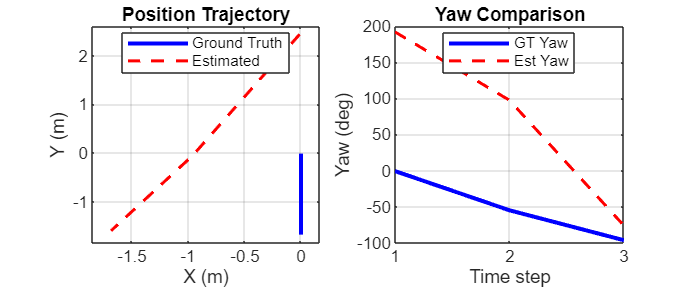

% 1. Calibrating sensors

% 2. Running EKF and storing RMSEs
task2_rmse = [0 0 0 0 0;
              0 0 0 0 0];
for i=1:1
    [X_Est, P_Est, GT] = myEKF(task2(i).out);

    disp("Task 2_" + num2str(i) + " RMSE: ");
    [pos_rmse, yaw_rmse] = calculateRMSE(X_Est, GT, task2(i).out.GT_rotation.signals.values);
    disp(['Position RMSE: ', num2str(pos_rmse), ' meters']);
    disp(['Yaw RMSE: ', num2str(rad2deg(yaw_rmse)), ' degrees']);

    visualiseTrajectory(X_Est, GT, sprintf('task2_%d', i));
end


% 3. Comparing tajectories
compareEKFTrajectory(X_Est, task2_1.out);

Error using new_state_vector>compareEKFTrajectory (line 318)
compareTrajectories failed. Reason: Undefined function 'compareTrajectories' for input arguments of type 'rigidtform3d'.
Ensure MATLAB R2024b+ with Navigation Toolbox.

function [X_Est, P_Est, GT] = myEKF(out)
    
    % Load calibration parameters (your style)
    calib_params = load('calib_params.mat');
    
    % Extract sensor data (your style)
    accel_raw = out.Sensor_ACCEL.signals.values;
    accel_squeezed = squeeze(accel_raw);
    gyro_raw = out.Sensor_GYRO.signals.values;
    gyro_squeezed = squeeze(gyro_raw);
    tof1_data = out.Sensor_ToF1.signals.values;
    tof2_data = out.Sensor_ToF2.signals.values;
    tof3_data = out.Sensor_ToF3.signals.values;
    
    % Time vectors (your style)
    time_vec = out.Sensor_ToF1.time;
    gt_time = out.GT_time.time;
    GT_position = out.GT_position.signals.values;
    GT_rotation = out.GT_rotation.signals.values;
    
    % Initial state from ground truth (your style)
    eul_angles = quat2eul(GT_rotation(1,:), 'ZYX');
    X = [GT_position(1,1);  % x
         GT_position(1,2);  % y
         eul_angles(1)];    % yaw
    
    % Initial covariance (your style naming)
    P = diag([0.010000, 0.010000, 0.007615]);
    
    % Process noise (using your Q naming style)
    Q_pos = 0.001;
    Q_yaw = 0.005;
    Q_accel = 0.01;
    
    % Main EKF loop
    n = length(time_vec);
    X_Est = zeros(3, n);
    P_Est = zeros(3, 3, n);
    GT = zeros(3, n);
    
    X_Est(:,1) = X;
    P_Est(:,:,1) = P;
    
    for k = 1:n-1
        dt = time_vec(k+1) - time_vec(k);
        
        % Get most recent IMU readings (your style indexing)
        imu_idx = find((0:length(gyro_squeezed)-1)*(1/104) <= time_vec(k+1), 1, 'last');
        
        % Apply your exact calibration method
        gyro_z_raw = -gyro_squeezed(3, imu_idx); % Z-axis gyro
        gyro_z = (deg2rad(gyro_z_raw) - calib_params.gyro_bias(3));
        
        accel_raw = accel_squeezed(:, imu_idx);
        accel_calib = accel_raw - calib_params.accel_bias';
        
        % Prediction step (example's logic with your calibration)
        R = [cos(X(3)) -sin(X(3)); 
             sin(X(3))  cos(X(3))];
        accel_world = R * accel_calib(1:2);
        
        % State prediction
        X_pred = X + [accel_world(1)*dt^2/2; 
                      accel_world(2)*dt^2/2;
                      gyro_z*dt];
        X_pred(3) = wrapToPi(X_pred(3));
        
        % Covariance prediction (your Q values)
        F = [1 0 -accel_world(2)*dt;
             0 1  accel_world(1)*dt;
             0 0  1];
         
        G = [dt^2/2 0      0;
             0      dt^2/2 0;
             0      0      dt];
         
        Q = diag([Q_pos, Q_pos, Q_yaw]) + G*diag([Q_accel, Q_accel, 0])*G';
        P_pred = F*P*F' + Q;
        
        % Update step with ToF (your style calibration)
        tof_readings = [tof1_data(k+1) - calib_params.tof_bias(1); 
                        tof2_data(k+1) - calib_params.tof_bias(2);
                        tof3_data(k+1) - calib_params.tof_bias(3)];
        
        valid_tof = tof_readings > 0;
        
        if any(valid_tof)
            H = zeros(sum(valid_tof), 3);
            z = zeros(sum(valid_tof), 1);
            R_tof = 0.01 * ones(sum(valid_tof), 1); % Your R value
            
            idx = 1;
            if valid_tof(1) % Forward ToF (your arena size)
                H(idx,:) = [0 1 0];
                z(idx) = tof_readings(1) - (1.2/2 - X_pred(2));
                idx = idx + 1;
            end
            if valid_tof(2) % Left ToF
                H(idx,:) = [1 0 0];
                z(idx) = tof_readings(2) - (1.2/2 + X_pred(1));
                idx = idx + 1;
            end
            if valid_tof(3) % Right ToF
                H(idx,:) = [1 0 0];
                z(idx) = tof_readings(3) - (1.2/2 - X_pred(1));
            end
            
            % Kalman update (your style)
            K = P_pred * H' / (H * P_pred * H' + diag(R_tof));
            X = X_pred + K * (z - H * X_pred);
            P = (eye(3) - K * H) * P_pred;
        else
            X = X_pred;
            P = P_pred;
        end
        
        % Store results (your style)
        X_Est(:,k+1) = X;
        P_Est(:,:,k+1) = P;
        
        % Store ground truth (your exact method)
        gt_idx = find(gt_time <= time_vec(k+1), 1, 'last');
        current_eul = quat2eul(GT_rotation(gt_idx,:), 'ZYX');
        GT(:,k+1) = [GT_position(gt_idx,1); 
                     GT_position(gt_idx,2); 
                     current_eul(1)];
    end
end

% RMSE Calculation
function [pos_rmse, yaw_rmse] = calculateRMSE(X_Est, GT, GT_rotation)
    
    % Ensure inputs are column vectors
    GT_x = GT(:,1);
    GT_y = GT(:,2);
    GT_yaw = GT(:,3);
    
    % Calculate position RMSE (X and Y combined)
    pos_error = sqrt((X_Est(:,1) - GT_x).^2 + (X_Est(:,2) - GT_y).^2);
    pos_rmse = sqrt(mean(pos_error.^2));
    
    % Calculate yaw RMSE
    est_yaw = X_Est(3,:);
    
    % Ensure both yaw vectors are same length
    min_len = min(length(est_yaw), length(GT_yaw));
    est_yaw = est_yaw(1:min_len);
    GT_yaw = GT_yaw(1:min_len);
    
    % Wrap angles to [-pi, pi] for proper difference calculation
    yaw_diff = wrapToPi(est_yaw - GT_yaw);
    yaw_rmse = sqrt(mean(yaw_diff.^2));

end

function angle = wrapToPi(angle)
    angle = mod(angle + pi, 2*pi) - pi;
end

function visualiseTrajectory(X_Est, GT, dataset_name)
    figure('Name', ['Trajectory: ', dataset_name], 'Position', [100 100 1200 500]);
    
    % Position Plot
    subplot(1,2,1);
    plot(GT(:,1), GT(:,2), 'b-', 'LineWidth', 2, 'DisplayName', 'Ground Truth');
    hold on;
    plot(X_Est(:,1), X_Est(:,2), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Estimated');
    %axis equal;
    
    % Set dynamic axis limits based on the data range
    min_x = min(min(GT(:,1)), min(X_Est(:,1)));
    max_x = max(max(GT(:,1)), max(X_Est(:,1)));
    min_y = min(min(GT(:,2)), min(X_Est(:,2)));
    max_y = max(max(GT(:,2)), max(X_Est(:,2)));
    
    % Add some padding around the axis limits to prevent data points from touching the edges
    padding = 0.1 * (max_x - min_x);
    
    xlim([min_x - padding, max_x + padding]);
    ylim([min_y - padding, max_y + padding]);
    
    xlabel('X (m)'); ylabel('Y (m)');
    title('Position Trajectory');
    legend('Location', 'best');
    grid on;
    
    % Yaw Plot
    subplot(1,2,2);
    t = 1:length(GT(:,3));
    plot(t, rad2deg(GT(:,3)), 'b-', 'LineWidth', 2, 'DisplayName', 'GT Yaw');
    hold on;
    plot(t, rad2deg(X_Est(:,5)), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Est Yaw');
    xlabel('Time step'); ylabel('Yaw (deg)');
    title('Yaw Comparison');
    legend('Location', 'best');
    grid on;
    
    % Save figure
    saveas(gcf, ['trajectory_', dataset_name, '.png']);
end

function compareEKFTrajectory(X_Est, out)
    
    % Extract and validate data
    pos_gt = out.GT_position.signals.values(:,1:3);  % X,Y,Z
    rot_gt = out.GT_rotation.signals.values;         % Quaternions [w,x,y,z]
    time = out.GT_time.time;
    
    % Truncate to common length
    N = min([length(time), size(pos_gt,1), size(X_Est,1)]);
    pos_gt = pos_gt(1:N,:);
    rot_gt = rot_gt(1:N,:);
    X_Est = X_Est(1:N,:);
    
    % ------------------ Create VALID rigidtform3d Objects ------------------ %
    % Preallocate
    gtTforms(N) = rigidtform3d();
    estTforms(N) = rigidtform3d();
    
    for i = 1:N
        % ---- Ground Truth Transform ----
        % 1. Convert quaternion to PROPER rotation matrix
        q_gt = quaternion(rot_gt(i,:));
        %if all(q_vals == 0) || norm(q_vals) < eps || any(isnan(q_vals))
        if all(q_gt==0)
            q_gt = quaternion(1, 0, 0, 0);
        end

        R_gt = rotmat(q_gt, 'frame');

        % 2. Force orthonormality (critical for rigidtform3d)
        [U,~,V] = svd(R_gt);
        R_gt_corrected = U * V';
        
        % 3. Create transform
        gtTforms(i) = rigidtform3d(R_gt_corrected, pos_gt(i,:));
        
        % ---- Estimated Transform ----
        % 1. Create yaw-only rotation matrix (Z-axis)
        yaw = X_Est(i,5);
        R_est = [cos(yaw) -sin(yaw) 0;
                 sin(yaw)  cos(yaw) 0;
                 0         0        1];
        
        % 2. Force Z=0 for 2D (required by brief)
        t_est = [X_Est(i,1), X_Est(i,2), 0];
        
        % 3. Create transform
        estTforms(i) = rigidtform3d(R_est, t_est);
    end
    
    % ------------------ compareTrajectories EXECUTION ------------------ %
    try
        % Ensure column vectors
        gtTforms = gtTforms(:);
        estTforms = estTforms(:);
        
        % Run comparison
        metrics = compareTrajectories(estTforms, gtTforms, 'AlignmentType', 'rigid');
        
        % Display results
        fprintf('\n=== Trajectory Comparison Results ===\n');
        fprintf('Absolute RMSE: %.4f m\n', metrics.AbsoluteRMSE(2));
        fprintf('Relative RMSE: %.4f m\n', metrics.RelativeRMSE(2));
        
        % Plot results
        figure('Position', [100 100 1200 400]);
        subplot(1,2,1);
        plot(metrics, 'absolute-translation');
        title('Absolute Position Error');
        
        subplot(1,2,2);
        plot(metrics, 'relative-translation');
        title('Relative Position Error');
        
    catch ME
        error('compareTrajectories failed. Reason: %s\nEnsure MATLAB R2024b+ with Navigation Toolbox.', ME.message);
    end
end